## Load Data

% MATLAB Script to Shortlist Candidates, Display Top Performers, and Perform Basic Analysis
clear all;
% Define the weights for each test
weight1 = 0.4;  % Weight for Aptitude
weight2 = 0.4;  % Weight for Reasoning
weight3 = 0.2;  % Weight for English

% Define the number of candidates
numCandidates = 1000;

% Generate random marks for each candidate between 0 and 100
rng(0);
marks = randi([0, 100], numCandidates, 3);

% Generate roll numbers
rollNumbers = (1:numCandidates)';


% Expanded lists of first and last names
firstNames = {'Alex', 'Jordan', 'Taylor', 'Morgan', 'Casey', 'Riley', 'Parker', 'Quinn', 'Reese', 'Sawyer', ...
              'Avery', 'Bailey', 'Cameron', 'Dakota', 'Emerson', 'Finley', 'Harper', 'Jesse', 'Kendall', ...
              'Logan', 'Charlie', 'Sam', 'Jamie', 'Drew', 'Skylar', 'Blake', 'Hayden', 'Rowan', 'Alexis', ...
              'Skyler', 'Terry','Jerry'};

lastNames = {'Smith', 'Johnson', 'Williams', 'Jones', 'Brown', 'Davis', 'Miller', 'Wilson', 'Moore', 'Taylor', ...
             'Anderson', 'Thomas', 'Jackson', 'White', 'Harris', 'Martin', 'Thompson', 'Garcia', 'Martinez', ...
             'Robinson', 'Clark', 'Rodriguez', 'Lewis', 'Lee', 'Walker', 'Hall', 'Allen', 'Young', 'King', ...
             'Wright', 'Scott','Tom'};

% Generate all possible combinations of first and last names
[fnIdx, lnIdx] = ndgrid(1:length(firstNames), 1:length(lastNames));
allCombinations = strcat(firstNames(fnIdx(:)), {' '}, lastNames(lnIdx(:)));

% Ensure there are enough combinations
if length(allCombinations) < 1000
    error('Not enough unique name combinations available.');
end

% Set random seed for reproducibility
rng(1);

% Randomly permute and select 1000 unique names
uniqueNames = allCombinations(randperm(length(allCombinations), 1000));

% Display the first 10 unique names as a sample
disp(uniqueNames(1:10));
names = strings(1000, 1);
names(:) = (uniqueNames(1,:));
save('MBA_project_data.mat');

## Calculate and Sort Weighted Data

load('MBA_project_data.mat');

% Create a table with roll numbers, names, and marks
candidateTable = table(rollNumbers, names, marks(:,1), marks(:,2), marks(:,3), ...
    'VariableNames', {'RollNumber', 'Name', 'Aptitude', 'Reasoning', 'English'});

% Calculate weighted scores
weightedScores = candidateTable.Aptitude * weight1 + candidateTable.Reasoning * weight2 + candidateTable.English * weight3;

% Add weighted scores to the table
candidateTable.WeightedScore = weightedScores;
candidateTable.SerialNumber = (1:size(candidateTable,1))';
candidateTable = candidateTable(:, {'SerialNumber','RollNumber','Name','Aptitude','Reasoning','English','WeightedScore'});


% Sort candidates by each test score and weighted score
sortedByAptitude = sortrows(candidateTable, {'Aptitude', 'WeightedScore'}, {'descend', 'descend'});
sortedByAptitude.SerialNumber = (1:size(sortedByAptitude,1))';
sortedByReasoning = sortrows(candidateTable, {'Reasoning', 'WeightedScore'}, {'descend', 'descend'});
sortedByReasoning.SerialNumber = (1:size(sortedByReasoning,1))';
sortedByEnglish = sortrows(candidateTable, {'English', 'WeightedScore'}, {'descend', 'descend'});
sortedByEnglish.SerialNumber = (1:size(sortedByEnglish,1))';
sortedByWeightedScore = sortrows(candidateTable, 'WeightedScore', 'descend');
sortedByWeightedScore.SerialNumber = (1:size(sortedByWeightedScore,1))';

% Add serial numbers for top candidates
top5Aptitude = sortedByAptitude(1:5,:);
top5Aptitude.SerialNumber = (1:5)';

top5Reasoning = sortedByReasoning(1:5,:);
top5Reasoning.SerialNumber = (1:5)';

top5English = sortedByEnglish(1:5,:);
top5English.SerialNumber = (1:5)';

top5Weighted = sortedByWeightedScore(1:5,:);
top5Weighted.SerialNumber = (1:5)';

top10Weighted = sortedByWeightedScore(1:10,:);
top10Weighted.SerialNumber = (1:10)';

% Retrieve top candidates
top5AptitudeName = sortedByAptitude(1:5, {'Name'});
top5ReasoningName = sortedByReasoning(1:5, {'Name'});
top5EnglishName = sortedByEnglish(1:5, {'Name'});
top5WeightedName = sortedByWeightedScore(1:5, {'Name'});
top10WeightedName = sortedByWeightedScore(1:10, {'Name'});

## Identification of Threshold

% Assume candidateTable is already created and contains the necessary columns

% Calculate the number of candidates in the top 30%
numCandidates = height(candidateTable);
top30PercentCount = round(0.3 * numCandidates);

% Identify thresholds for each category
thresholds.Aptitude = sortedByAptitude.Aptitude(top30PercentCount);
thresholds.Reasoning = sortedByReasoning.Reasoning(top30PercentCount);
thresholds.English = sortedByEnglish.English(top30PercentCount);
thresholds.WeightedScore = sortedByWeightedScore.WeightedScore(top30PercentCount);

% Display the determined thresholds
disp('Determined Thresholds for Top 30% in Each Category:');

Determined Thresholds for Top 30% in Each Category:




% Filter candidates who are in the top 30% for all categories
filteredCandidates_threshold = candidateTable(...
    (candidateTable.Aptitude >= thresholds.Aptitude) & ...
    (candidateTable.Reasoning >= thresholds.Reasoning) & ...
    (candidateTable.English >= thresholds.English) & ...
    (candidateTable.WeightedScore >= thresholds.WeightedScore), :);

% Display filtered candidates
disp('Candidates in the Top 30% for All Categories:');

Candidates in the Top 30% for All Categories:



filteredCandidates_threshold = sortrows(filteredCandidates_threshold, 'WeightedScore', 'descend');
filteredCandidates_threshold.SerialNumber = (1:size(filteredCandidates_threshold,1))';
disp(filteredCandidates_threshold);

    SerialNumber    RollNumber           Name           Aptitude    Reasoning    English    WeightedScore
    ____________    __________    __________________    ________    _________    _______    _____________

          1            982        "Parker Lewis"           92           95         82           91.2     
          2            288        "Harper Jackson"         99           80         96           90.8     
          3            583        "Alexis Clark"           95           89         82             90     
          4            147        "Morgan Williams"        97           83         88           89.6     
          5             64        "Cameron Young"          95           91         74           89.2     
          6        

% Save the filtered data as a variable in the workspace
variableName = 'filtered_top_30_percent_all_categories';
assignin('base', variableName, filteredCandidates_threshold);

% Calculate the minimum thresholds from the filtered candidates
minThresholds.Aptitude = min(filteredCandidates_threshold.Aptitude);
minThresholds.Reasoning = min(filteredCandidates_threshold.Reasoning);
minThresholds.English = min(filteredCandidates_threshold.English);
minThresholds.WeightedScore = min(filteredCandidates_threshold.WeightedScore);

% Display the minimum thresholds
disp('Minimum Thresholds from Filtered Candidates:');

Minimum Thresholds from Filtered Candidates:


disp(minThresholds);

         Aptitude: 69
        Reasoning: 71
          English: 69
    WeightedScore: 76.8000




% Confirmation message
fprintf('Data saved as variable "%s" in the workspace.\n', variableName);

Data saved as variable "filtered_top_30_percent_all_categories" in the workspace.


## Visualize Data

figures = findall(0, 'Type', 'figure');

% Close each of these figures
close(figures)
% Create a simple GUI to display the results
fig = uifigure('Name', 'Top Candidates', 'Position', [100, 100, 600, 400]);

% Create tabs for each result category
tabGroup = uitabgroup(fig);

tab1 = uitab(tabGroup, 'Title', 'Data Visualization Based on Average in Each Test');
tab2 = uitab(tabGroup, 'Title', 'Data Visualization for Histogram Distribution of Weighted Scores');
tab3 = uitab(tabGroup, 'Title', 'Data Visualization for Pie Graph for Distribution of Weighted Scores in Specific Bracket');


% Data Visualization: Add a bar chart for average scores
% Calculate average scores for each test
averageScores = mean(marks);


% Create a bar chart in the Data Visualization tab
ax = uiaxes('Parent', tab1, 'Position', [20, 20, 560, 350]);
bar(ax, averageScores);
ax.Title.String = 'Average Scores for Each Test';
ax.XLabel.String = 'Test';
ax.YLabel.String = 'Average Score';
ax.XTickLabel = {'Aptitude', 'Reasoning', 'English'};

% Top 20 candidates for each test
top20Aptitude = sortedByAptitude(1:20, :);
top20Reasoning = sortedByReasoning(1:20, :);
top20English = sortedByEnglish(1:20, :);
top20Weighted = sortedByWeightedScore(1:20, :);



ax3 = uiaxes('Parent', tab2, 'Position', [20, 20, 560, 350]);
histogram(ax3, candidateTable.WeightedScore, 'BinWidth', 5);
ax3.Title.String = 'Distribution of Weighted Scores';
ax3.XLabel.String = 'Weighted Score';
ax3.YLabel.String = 'Frequency';

% Continue the script for another enhancement

% Define score ranges
scoreRanges = [0 50; 51 60; 61 70; 71 80; 81 90; 91 100];
rangeLabels = {'0-50', '51-60', '61-70', '71-80', '81-90', '91-100'};

% Calculate the number of candidates in each score range
numInRange = zeros(size(scoreRanges, 1), 1);
for i = 1:size(scoreRanges, 1)
    numInRange(i) = sum(candidateTable.WeightedScore >= scoreRanges(i, 1) & candidateTable.WeightedScore <= scoreRanges(i, 2));
end

% Pie chart for score distribution
ax4 = uiaxes('Parent', tab3, 'Position', [20, 20, 560, 350]);
pie(ax4, numInRange);
ax4.Title.String = 'Percentage of Candidates in Score Ranges';
legend(ax4, rangeLabels, 'Location', 'eastoutside');

% Continue the script for another enhancement

% Filter candidates with weighted scores >= minThresholds.WeightedScore
% candidatesAboveThreshold = candidateTable(candidateTable.WeightedScore >= minThresholds.WeightedScore, :);
candidatesAboveThreshold = filteredCandidates_threshold

candidatesAboveThreshold = 20×7 table
    SerialNumber    RollNumber           Name           Aptitude    Reasoning    English    WeightedScore
    ____________    __________    __________________    ________    _________    _______    _____________

          1            982        "Parker Lewis"           92           95         82           91.2     
          2            288        "Harper Jackson"         99           80         96           90.8     
          3            583        "Alexis Clark"           95           89         82             90     
          4            147        "Morgan Williams"        97           83         88           89.6     
          5             64        "Cameron Young"          95           91         74  

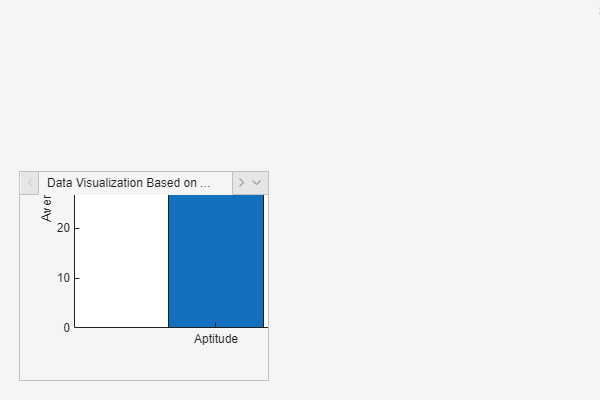

% Add serial numbers for candidates above the threshold



% Add tables to each tab with proper positioning and cell selection callback
tab4 = uitab(tabGroup, 'Title', 'Interactive Top 5 Weighted');
tab5 = uitab(tabGroup, 'Title', 'Interactive Top 10 Weighted');
tab6 = uitab(tabGroup, 'Title', 'Interactive Candidates Above Threshold Weighted');

uitable('Parent', tab4, 'Data', top5Weighted(:, {'SerialNumber', 'RollNumber', 'Name', 'WeightedScore'}), ...
    'Position', [20, 20, 560, 350], 'CellSelectionCallback', @(src, event) displayCandidateDetails(event, sortedByWeightedScore));
uitable('Parent', tab5, 'Data', top10Weighted(:, {'SerialNumber', 'RollNumber', 'Name', 'WeightedScore'}), ...
    'Position', [20, 20, 560, 350], 'CellSelectionCallback', @(src, event) displayCandidateDetails(event, sortedByWeightedScore));
uitable('Parent', tab6, 'Data', candidatesAboveThreshold, ...
    'Position', [20, 20, 560, 350], 'CellSelectionCallback', @(src, event) displayCandidateDetails(event, candidatesAboveThreshold));

tab14 = uitab(tabGroup, 'Title', 'Interactive All Candidates Sorted by Weighted Marks');
sortedCandidates =  sortrows(candidateTable, 'WeightedScore', 'descend');
sortedCandidates.SerialNumber = (1:size(sortedCandidates,1))';
sortedCandidates = sortedCandidates(:, {'SerialNumber','RollNumber','Name','Aptitude','Reasoning','English','WeightedScore'});
uitable('Parent', tab14, 'Data', sortedCandidates(:, {'SerialNumber', 'RollNumber', 'Name', 'WeightedScore'}), ...
    'Position', [20, 20, 560, 350], 'CellSelectionCallback', @(src, event) displayCandidateDetails(event, sortedCandidates));

% Function to display candidate details
function displayCandidateDetails(event, sortedTable)
    if isempty(event.Indices)
        return;
    end
    selectedIndex = event.Indices(1);
    selectedCandidate = sortedTable(selectedIndex, :);
    
    % Create a new figure for candidate details
    detailFig = uifigure('Name', ['Details for ', selectedCandidate.Name{1}], 'Position', [200, 200, 400, 200]);
    
    % Display candidate details
    uilabel(detailFig, 'Text', ['Roll Number: ', num2str(selectedCandidate.RollNumber)], 'Position', [20, 150, 360, 20]);
    uilabel(detailFig, 'Text', ['Name: ', selectedCandidate.Name{1}], 'Position', [20, 120, 360, 20]);
    uilabel(detailFig, 'Text', ['Aptitude Score: ', num2str(selectedCandidate.Aptitude)], 'Position', [20, 90, 360, 20]);
    uilabel(detailFig, 'Text', ['Reasoning Score: ', num2str(selectedCandidate.Reasoning)], 'Position', [20, 60, 360, 20]);
    uilabel(detailFig, 'Text', ['English Score: ', num2str(selectedCandidate.English)], 'Position', [20, 30, 360, 20]);
    uilabel(detailFig, 'Text', ['Weighted Score: ', num2str(selectedCandidate.WeightedScore)], 'Position', [20, 0, 360, 20]);
end


% Add a search bar and button in the main figure
uilabel(fig, 'Text', 'Search Candidate:', 'Position', [600, 380, 100, 20]);
searchField = uieditfield(fig, 'text', 'Position', [700, 380, 150, 20]);
searchButton = uibutton(fig, 'Text', 'Search', 'Position', [860, 380, 80, 20], ...
    'ButtonPushedFcn', @(btn, event) searchCandidate(searchField.Value, candidateTable));

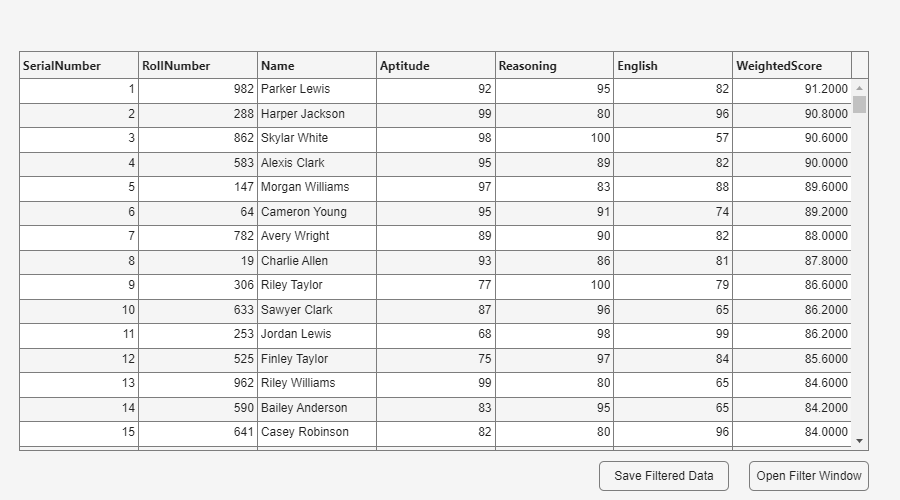


excelFile = 'Results_data.xlsx';
writetable(candidateTable, excelFile, 'Sheet', 'EntireData');

excelFile = 'Results_data.xlsx';
writetable(sortedCandidates, excelFile, 'Sheet', 'EntireDataSortedWithWeights');

excelFile = 'Results_data.xlsx';
writetable(candidatesAboveThreshold, excelFile, 'Sheet', 'PotentialCandidates');


% Function to search for a candidate by roll number or name
function searchCandidate(searchTerm, candidateTable)
    if isempty(searchTerm)
        uialert(fig, 'Please enter a roll number or name to search.', 'Input Required');
        return;
    end
    
    % Search by roll number or name
    isMatch = strcmpi(candidateTable.RollNumber, searchTerm) | contains(candidateTable.Name, searchTerm, 'IgnoreCase', true);
    matchedCandidates = candidateTable(isMatch, :);
    
    if isempty(matchedCandidates)
        uialert(fig, 'No matching candidate found.', 'Search Result');
    else
        % Display details of the first matched candidate
        selectedCandidate = matchedCandidates(1, :);
        
        % Create a new figure for candidate details
        detailFig = uifigure('Name', ['Details for ', selectedCandidate.Name{1}], 'Position', [200, 200, 400, 200]);
        
        % Display candidate details
        uilabel(detailFig, 'Text', ['Roll Number: ', num2str(selectedCandidate.RollNumber)], 'Position', [20, 150, 360, 20]);
        uilabel(detailFig, 'Text', ['Name: ', selectedCandidate.Name{1}], 'Position', [20, 120, 360, 20]);
        uilabel(detailFig, 'Text', ['Aptitude Score: ', num2str(selectedCandidate.Aptitude)], 'Position', [20, 90, 360, 20]);
        uilabel(detailFig, 'Text', ['Reasoning Score: ', num2str(selectedCandidate.Reasoning)], 'Position', [20, 60, 360, 20]);
        uilabel(detailFig, 'Text', ['English Score: ', num2str(selectedCandidate.English)], 'Position', [20, 30, 360, 20]);
        uilabel(detailFig, 'Text', ['Weighted Score: ', num2str(selectedCandidate.WeightedScore)], 'Position', [20, 0, 360, 20]);
    end
end
% Main figure setup
mainFig = uifigure('Name', 'Candidate Management', 'Position', [100, 100, 900, 500]);

% Table to display candidates in the main figure
FilteredCandidateTable = uitable('Parent', mainFig, 'Data', sortedCandidates, ...
    'Position', [20, 50, 850, 400], 'ColumnName', sortedCandidates.Properties.VariableNames);

% Button to open the filter window
openFilterWindowButton = uibutton(mainFig, 'Text', 'Open Filter Window', ...
    'Position', [750, 10, 120, 30], 'ButtonPushedFcn', @(btn, event) openFilterWindow(sortedCandidates, FilteredCandidateTable));

% Button to save the filtered data as a variable in the workspace
saveButton = uibutton(mainFig, 'Text', 'Save Filtered Data', ...
    'Position', [600, 10, 130, 30], 'ButtonPushedFcn', @(btn, event) saveFilteredData(FilteredCandidateTable));


% Function to open the filter window
function openFilterWindow(sortedCandidates, FilteredCandidateTable)
    % Create a new figure for filtering
    filterFig = uifigure('Name', 'Filter Candidates', 'Position', [350, 350, 400, 200]);
    
    % Add dropdown and numeric input for filtering by marks in the filter figure
    marksDropdown = uidropdown(filterFig, 'Items', {'Aptitude', 'Reasoning', 'English', 'Weighted Average'}, ...
        'Position', [20, 120, 150, 22], 'Value', 'Aptitude');
    
    thresholdInput = uieditfield(filterFig, 'numeric', 'Position', [200, 120, 100, 22]);
    
    filterMarksButton = uibutton(filterFig, 'Text', 'Apply Filter', ...
        'Position', [310, 120, 80, 22], 'ButtonPushedFcn', @(btn, event) filterCandidatesByMarks(sortedCandidates, FilteredCandidateTable, marksDropdown.Value, thresholdInput.Value));
end

% Function to filter candidates based on marks
function filterCandidatesByMarks(sortedCandidates, FilteredCandidateTable, criteria, threshold)
    if isnan(threshold)
        uialert(mainFig, 'Please enter a valid numeric threshold.', 'Invalid Input');
        return;
    end
    
    switch criteria
        case 'Aptitude'
            filteredCandidates = sortedCandidates(sortedCandidates.Aptitude >= threshold, :);
            filteredCandidates.SerialNumber = (1:size(filteredCandidates,1))';
            filteredCandidates = filteredCandidates(:, {'SerialNumber','RollNumber','Name','Aptitude','WeightedScore'});
        case 'Reasoning'
            filteredCandidates = sortedCandidates(sortedCandidates.Reasoning >= threshold, :);
            filteredCandidates.SerialNumber = (1:size(filteredCandidates,1))';
            filteredCandidates = filteredCandidates(:, {'SerialNumber','RollNumber','Name','Reasoning','WeightedScore'});
        case 'English'
            filteredCandidates = sortedCandidates(sortedCandidates.English >= threshold, :);
            filteredCandidates.SerialNumber = (1:size(filteredCandidates,1))';
            filteredCandidates = filteredCandidates(:, {'SerialNumber','RollNumber','Name','English','WeightedScore'});
        case 'Weighted Average'
            filteredCandidates = sortedCandidates(sortedCandidates.WeightedScore >= threshold, :);
            filteredCandidates.SerialNumber = (1:size(filteredCandidates,1))';
            filteredCandidates = filteredCandidates(:, {'SerialNumber','RollNumber','Name','WeightedScore'});
    end
    
    % Update the display table in the main figure with filtered candidates
    FilteredCandidateTable.Data = filteredCandidates;
    FilteredCandidateTable.UserData.Criteria = criteria;
    FilteredCandidateTable.UserData.Threshold = threshold;
    FilteredCandidateTable.ColumnName = filteredCandidates.Properties.VariableNames;
end

% Function to save the filtered data as a variable in the workspace
function saveFilteredData(FilteredCandidateTable)
    % Get the data and filtering criteria from the table
    data = FilteredCandidateTable.Data;
    criteria = FilteredCandidateTable.UserData.Criteria;
    threshold = FilteredCandidateTable.UserData.Threshold;
    
    % Create a dynamic variable name based on criteria and threshold
    variableName = sprintf('%s_%d', lower(criteria), threshold);
    variableName = matlab.lang.makeValidName(variableName); % Ensure valid variable name
    
    % Assign the data to a variable in the base workspace
    assignin('base', variableName, data);

    % Use the variable name as the .mat file name
    matFileName = strcat(variableName, '.mat');

    % Save the variable from the base workspace to the .mat file
    evalin('base', sprintf('save(''%s'', ''%s'')', matFileName, variableName));
    % save(variableName,data);
    % Show a confirmation message
    % Show a confirmation message
    uialert(FilteredCandidateTable.Parent, sprintf('Data saved as variable "%s" in the workspace.', variableName), 'Success');
end


% Display the figure
fig.Visible = 'on';

## Dynamic Filtering

% Main figure setup
figures = findall(0, 'Type', 'figure');
close(figures);
mainFig2 = uifigure('Name', 'Candidate Management_v3', 'Position', [100, 100, 900, 500]);

% Table to display candidates in the main figure
FilteredCandidateTable2 = uitable('Parent', mainFig2, 'Data', sortedCandidates, ...
    'Position', [20, 50, 850, 400], 'ColumnName', sortedCandidates.Properties.VariableNames);

% Button to open the filter window
openFilterWindowButton = uibutton(mainFig2, 'Text', 'Open Filter Window', ...
    'Position', [750, 10, 120, 30], 'ButtonPushedFcn', @(btn, event) openFilterWindow_v3(sortedCandidates, FilteredCandidateTable2));

% Button to save the filtered data as a variable in the workspace
saveButton = uibutton(mainFig2, 'Text', 'Save Filtered Data', ...
    'Position', [600, 10, 130, 30], 'ButtonPushedFcn', @(btn, event) saveFilteredData_v3(FilteredCandidateTable2));


% Function to open the filter window
function openFilterWindow_v3(sortedCandidates, FilteredCandidateTable2)
    % Create a new figure for filtering
    filterFig = uifigure('Name', 'Filter Candidates', 'Position', [350, 350, 400, 300]);
    
    % Add labels and numeric inputs for each threshold
    uilabel(filterFig, 'Text', 'Aptitude Threshold:', 'Position', [20, 240, 150, 22]);
    aptitudeThresholdInput = uieditfield(filterFig, 'numeric', 'Position', [200, 240, 100, 22], 'Placeholder', 'Aptitude Threshold');
    
    uilabel(filterFig, 'Text', 'Reasoning Threshold:', 'Position', [20, 200, 150, 22]);
    reasoningThresholdInput = uieditfield(filterFig, 'numeric', 'Position', [200, 200, 100, 22], 'Placeholder', 'Reasoning Threshold');
    
    uilabel(filterFig, 'Text', 'English Threshold:', 'Position', [20, 160, 150, 22]);
    englishThresholdInput = uieditfield(filterFig, 'numeric', 'Position', [200, 160, 100, 22], 'Placeholder', 'English Threshold');
    
    uilabel(filterFig, 'Text', 'Weighted Score Threshold:', 'Position', [20, 120, 150, 22]);
    weightedAvgThresholdInput = uieditfield(filterFig, 'numeric', 'Position', [200, 120, 100, 22], 'Placeholder', 'Weighted Avg Threshold');
    
    % Button to apply filter
    filterMarksButton = uibutton(filterFig, 'Text', 'Apply Filter', ...
        'Position', [310, 140, 80, 22], 'ButtonPushedFcn', @(btn, event) filterCandidatesByMarks_v3(sortedCandidates, FilteredCandidateTable2, aptitudeThresholdInput.Value, reasoningThresholdInput.Value, englishThresholdInput.Value, weightedAvgThresholdInput.Value));
end

% Function to filter candidates based on marks
function filterCandidatesByMarks_v3(sortedCandidates, FilteredCandidateTable2, aptitudeThreshold, reasoningThreshold, englishThreshold, weightedAvgThreshold)
    if isnan(aptitudeThreshold) || isnan(reasoningThreshold) || isnan(englishThreshold) || isnan(weightedAvgThreshold)
        uialert(FilteredCandidateTable2.Parent, 'Please enter valid numeric thresholds for all fields.', 'Invalid Input');
        return;
    end
    
    % Apply filtering based on all thresholds
    filteredCandidates = sortedCandidates(sortedCandidates.Aptitude >= aptitudeThreshold & ...
                                          sortedCandidates.Reasoning >= reasoningThreshold & ...
                                          sortedCandidates.English >= englishThreshold & ...
                                          sortedCandidates.WeightedScore >= weightedAvgThreshold, :);
    filteredCandidates.SerialNumber = (1:size(filteredCandidates,1))';
    filteredCandidates = filteredCandidates(:, {'SerialNumber','RollNumber','Name','Aptitude','Reasoning','English','WeightedScore'});
    % Update the display table in the main figure with filtered candidates
    FilteredCandidateTable2.Data = filteredCandidates;
    FilteredCandidateTable2.UserData.AptitudeThreshold = aptitudeThreshold;
    FilteredCandidateTable2.UserData.ReasoningThreshold = reasoningThreshold;
    FilteredCandidateTable2.UserData.EnglishThreshold = englishThreshold;
    FilteredCandidateTable2.UserData.WeightedScore = weightedAvgThreshold;
% Update the column names to reflect the filtered candidates
    FilteredCandidateTable2.ColumnName = filteredCandidates.Properties.VariableNames;
end

% Function to save the filtered data as a variable in the workspace
function saveFilteredData_v3(FilteredCandidateTable2)
    % Get the data and filtering thresholds from the table
    data = FilteredCandidateTable2.Data;
    
    % Retrieve the thresholds from UserData
    aptitudeThreshold = FilteredCandidateTable2.UserData.AptitudeThreshold;
    reasoningThreshold = FilteredCandidateTable2.UserData.ReasoningThreshold;
    englishThreshold = FilteredCandidateTable2.UserData.EnglishThreshold;
    weightedAvgThreshold = FilteredCandidateTable2.UserData.WeightedScore;
    
    % Create a dynamic variable name based on thresholds
    variableName = sprintf('filtered_apt_%d_reason_%d_eng_%d_weighted_%d', ...
                           aptitudeThreshold, reasoningThreshold, englishThreshold, weightedAvgThreshold);
    variableName = matlab.lang.makeValidName(variableName); % Ensure valid variable name
    
    % Assign the data to a variable in the base workspace
    assignin('base', variableName, data);

    % Use the variable name as the .mat file name
    matFileName = strcat(variableName, '.mat');

    % Save the variable from the base workspace to the .mat file
    evalin('base', sprintf('save(''%s'', ''%s'')', matFileName, variableName));
    
    % Show a confirmation message
    uialert(FilteredCandidateTable2.Parent, sprintf('Data saved as variable "%s" in the workspace.', variableName), 'Success');
end

% Ensure the main figure is visible
mainFig2.Visible = 'on';
